% % MILP problem to risk appetite model
clc
clear all

% % Loading data set
IS = xlsread("Utility_estimation.xlsx",'IS_SU'); % Information System from respondent evaluations
Data_based_case = xlsread('Utility_estimation.xlsx','DT_SU'); % Utility estimation from RSGA


% % Define the features
U = Data_based_case(:,1); % Number of observation
Utility_R = round(Data_based_case(:,1:end-1)); % Number of utility estimation

Cond_R = IS(:,1:end-1); % Number of conditional seaport risk factors

Dec_R = Data_based_case(:,end); % Decisional seaport risk factor


% % Formulating the problem
utilityprob = optimproblem("ObjectiveSense","minimize")

utilityprob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [0×0 struct] containing 0 OptimizationVariables
         Objective: [0×0 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  No problem defined.


e = optimvar('e',71,61,'Type','integer','LowerBound',0,'UpperBound',1);
show(e)

    [ e(1, 1)     e(1, 2)     e(1, 3)     e(1, 4)     e(1, 5)     e(1, 6)     e(1, 7)     e(1, 8)     e(1, 9)     e(1, 10)     e(1, 11)     e(1, 12)     e(1, 13)     e(1, 14)     e(1, 15)     e(1, 16)     e(1, 17)     e(1, 18)     e(1, 19)     e(1, 20)     e(1, 21)     e(1, 22)     e(1, 23)     e(1, 24)     e(1, 25)     e(1, 26)     e(1, 27)     e(1, 28)     e(1, 29)     e(1, 30)     e(1, 31)     e(1, 32)     e(1, 33)     e(1, 34)     e(1, 35)     e(1, 36)     e(1, 37)     e(1, 38)     e(1, 39)     e(1, 40)     e(1, 41)     e(1, 42)     e(1, 43)     e(1, 44)     e(1, 45)     e(1, 46)     e(1, 47)     e(1, 48)     e(1, 49)     e(1, 50)     e(1, 51)     e(1, 52)     e(1, 53)     e(1, 54)     e(1, 55)     e(1, 56)     e(1, 57)     e(1, 58)     e(1, 59)     e(1, 60)     e(1, 61)  ]
    [ e(2, 1)     e(2, 2)     e(2, 3)     e(2, 4)     e(2, 5)     e(2, 6)     e(2, 7)     e(2, 8)     e(2, 9)     e(2, 10)     e(2, 11)     e(2, 12)     e(2, 13)     e(2, 14)     e(2, 15)     e(2, 16)     e(2, 1

utilityEstimation = Utility_R;
riskPreferences = Cond_R;
Decisional_SR = Dec_R;
Percentage_utility = Utility_R.*Decisional_SR

Percentage_utility =   -298  -298   -86    82    46   194   208    58    94   -32  -204    68    68  -204   110   194   236   100   134  -154  -350    36   236   114  -350  -160    82   112   -90  -178     4   102   126    24  -180  -180   160   176   -78   188  -268  -268   336    88  -216   424  -210   184   224  -408
   225  -354   240  -111   -18  -378   312    36    45  -426   531  -450  -174   444    45    27   126  -378   -93   576   357  -378  -402   -63   255  -534   372   420    87  -534   438  -255     3   342   126   312  -534  -249  -168    48   270   330  -378  -102  -207   195    12   300  -153  -147
   -80    -6   170  -226   148   -42   216    32  -212   358  -208   102   180  -208   -18  -208   210   -38  -376   100   278    10  -354   -26   196   178  -292    42   290    32  -312    16    46  -118   118    98   -22   -74  -186  -176   418  -186  -186   316     4    -2    -2  -320   160   160
    84  -162  -158   -12    74   204   142   -42  -128     6  -268   -28    

Freq_entities = length(Utility_R)/3

Freq_entities = 23.6667

F = 1./Freq_entities

F = 0.0423

pwra_utility = abs(Utility_R.^0.05)

pwra_utility =     1.2843    1.2843    1.2069    1.2040    1.1697    1.2570    1.2614    1.1834    1.2123    1.1487    1.2602    1.1928    1.1928    1.2602    1.2219    1.2570    1.2694    1.2160    1.2340    1.2426    1.2946    1.1555    1.2694    1.2240    1.2946    1.2450    1.2040    1.2230    1.2097    1.2516    1.0353    1.2172    1.2302    1.1323    1.2523    1.2523    1.2450    1.2509    1.2010    1.2550    1.2775    1.2775    1.2920    1.2083    1.2638    1.3071    1.2620    1.2537    1.2661    1.3046
    1.2409    1.2694    1.2450    1.1979    1.0937    1.2736    1.2614    1.1323    1.1450    1.2812    1.2954    1.2847    1.2251    1.2838    1.1450    1.1161    1.2055    1.2736    1.1873    1.3007    1.2699    1.2736    1.2775    1.1644    1.2487    1.2957    1.2725    1.2803    1.1834    1.2957    1.2830    1.2487    1.0000    1.2672    1.2055    1.2614    1.2957    1.2473    1.2230    1.1487    1.2523    1.2649    1.2736    1.1928    1.2358    1.2321    1.0718    1.2589    

predprob = pwra_utility/sum(pwra_utility(:))

predprob = 1.0e-03 *

    0.2438    0.2438    0.2291    0.2285    0.2220    0.2386    0.2394    0.2246    0.2301    0.2180    0.2392    0.2264    0.2264    0.2392    0.2319    0.2386    0.2409    0.2308    0.2342    0.2358    0.2457    0.2193    0.2409    0.2323    0.2457    0.2363    0.2285    0.2321    0.2296    0.2376    0.1965    0.2310    0.2335    0.2149    0.2377    0.2377    0.2363    0.2374    0.2280    0.2382    0.2425    0.2425    0.2452    0.2293    0.2399    0.2481    0.2395    0.2380    0.2403    0.2476
    0.2355    0.2409    0.2363    0.2274    0.2076    0.2417    0.2394    0.2149    0.2173    0.2432    0.2459    0.2438    0.2325    0.2437    0.2173    0.2118    0.2288    0.2417    0.2254    0.2469    0.2410    0.2417    0.2425    0.2210    0.2370    0.2459    0.2415    0.2430    0.2246    0.2459    0.2435    0.2370    0.1898    0.2405    0.2288    0.2394    0.2459    0.2367    0.2321    0.2180    0.2377    0.2401    0.2417    0.2264    0.2346    0.2339    0.2034    0.2

% % Creating expressions
Z = F.*sum(sum(Cond_R.*predprob.*utilityEstimation.*e))

Z =   Linear OptimizationExpression

    -0.0015347*e(1, 1) + 0.0037321*e(2, 1) - 0.0011573*e(3, 1) + 0.0020303*e(4, 1) - 0.0023385*e(5, 1) + 0.00026996*e(6, 1) + 0.006972*e(7, 1) + 0.0034193*e(8, 1) - 0.0013944*e(9, 1) - 0.00079181*e(10, 1) - 0.0018716*e(11, 1) + 0.00041323*e(12, 1) + 0.0027117*e(13, 1) - 0.0012846*e(14, 1) - 0.0013677*e(15, 1) - 0.00052964*e(16, 1) + 0.0022794*e(17, 1) - 0.00012375*e(18, 1) + 0.0020736*e(19, 1) + 0.0062739*e(20, 1) + 0.0020736*e(21, 1) - 0.0016105*e(22, 1) + 0.0056862*e(23, 1) - 0.001181*e(24, 1) - 0.00070619*e(25, 1) + 0.00047126*e(26, 1) + 0.0012609*e(27, 1) + 0.0024448*e(28, 1) + 0.0005896*e(29, 1) - 2.406e-05*e(30, 1) + 0.0013815*e(31, 1) - 0.0020905*e(32, 1) + 0.00041323*e(33, 1) + 0.0071336*e(34, 1) + 0.0024448*e(35, 1) + 0.00024168*e(36, 1) - 0.00070653*e(37, 1) + 0.0038367*e(38, 1) - 0.0011479*e(39, 1) + 0.0057928*e(40, 1) - 0.00010167*e(41, 1) + 0

utilityprob.Objective = Z; % Objective function
show(Z)


  -0.0015347*e(1, 1) + 0.0037321*e(2, 1)
- 0.0011573*e(3, 1) + 0.0020303*e(4, 1)
- 0.0023385*e(5, 1) + 0.00026996*e(6, 1)
+ 0.006972*e(7, 1) + 0.0034193*e(8, 1)
- 0.0013944*e(9, 1) - 0.00079181*e(10, 1)
- 0.0018716*e(11, 1) + 0.00041323*e(12, 1)
+ 0.0027117*e(13, 1) - 0.0012846*e(14, 1)
- 0.0013677*e(15, 1) - 0.00052964*e(16, 1)
+ 0.0022794*e(17, 1) - 0.00012375*e(18, 1)
+ 0.0020736*e(19, 1) + 0.0062739*e(20, 1)
+ 0.0020736*e(21, 1) - 0.0016105*e(22, 1)
+ 0.0056862*e(23, 1) - 0.001181*e(24, 1)
- 0.00070619*e(25, 1) + 0.00047126*e(26, 1)
+ 0.0012609*e(27, 1) + 0.0024448*e(28, 1)
+ 0.0005896*e(29, 1) - 2.406e-05*e(30, 1)
+ 0.0013815*e(31, 1) - 0.0020905*e(32, 1)
+ 0.00041323*e(33, 1) + 0.0071336*e(34, 1)
+ 0.0024448*e(35, 1) + 0.00024168*e(36, 1)
- 0.00070653*e(37, 1) + 0.0038367*e(38, 1)
- 0.0011479*e(39, 1) + 0.0057928*e(40, 1)
- 0.00010167*e(41, 1) + 0.0019915*e(42, 1)
+ 0.0012486*e(43, 1) + 0.0038268*e(44, 1)
- 0.0015766*e(45, 1) + 0.0034713*e(46, 1)
- 0.0014375*e(47, 1) + 0.0010213

% % Defining constaints
for m = 1:71
    for n = 1:61
        if utilityEstimation(m,n) ~= utilityEstimation(n)
            d_ikj(m,n) = 1;
        else
            d_ikj(m,n) = 0;
        end
    end
end

d_ikj_cons1 = sum(d_ikj.*e) <= 1

d_ikj_cons1 =   1×61 Linear OptimizationInequality array with properties:

    IndexNames: {{}  {}}
     Variables: [1×1 struct] containing 1 OptimizationVariable

  See inequality formulation with show.


utilityprob.Constraints.d_ikj_cons1 = d_ikj_cons1

utilityprob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 1 OptimizationConstraint

  See problem formulation with show.


% % Solve the problem
[sol, fval] = solve(utilityprob)

Solving problem using intlinprog.
LP:                Optimal objective value is -0.172268.                                            


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the
optimal value, options.AbsoluteGapTolerance = 0 (the
default value). The intcon variables are
integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



sol = struct with fields:
    e: [71×61 double]


fval = -0.1723

sol.e

ans =      1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     1     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0 

fval

fval = -0.1723

% % Plotting result
h = heatmap(sol.e)

h =   HeatmapChart with properties:

        XData: {61×1 cell}
        YData: {71×1 cell}
    ColorData: [71×61 double]

  Show all properties


h.Title = 'Risk appetite of seaport-user under Scenario III'

h =   HeatmapChart (Risk appetite of seaport-user under Scenario III) with properties:

        XData: {61×1 cell}
        YData: {71×1 cell}
    ColorData: [71×61 double]

  Show all properties


h.XLabel = 'Conditional seaport risk factors'

h =   HeatmapChart (Risk appetite of seaport-user under Scenario III) with properties:

        XData: {61×1 cell}
        YData: {71×1 cell}
    ColorData: [71×61 double]

  Show all properties


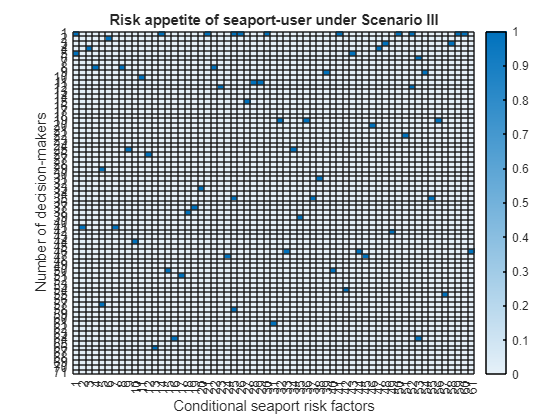

h =   HeatmapChart (Risk appetite of seaport-user under Scenario III) with properties:

        XData: {61×1 cell}
        YData: {71×1 cell}
    ColorData: [71×61 double]

  Show all properties


h.YLabel = 'Number of decision-makers'


s = surf(sol.e)

s =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [71×1 double]
           ZData: [71×61 double]
           CData: [71×61 double]

  Show all properties


s.EdgeColor = "interp"

s =   Surface with properties:

       EdgeColor: 'interp'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [71×1 double]
           ZData: [71×61 double]
           CData: [71×61 double]

  Show all properties


s.FaceColor = "interp"

s =   Surface with properties:

       EdgeColor: 'interp'
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [71×1 double]
           ZData: [71×61 double]
           CData: [71×61 double]

  Show all properties


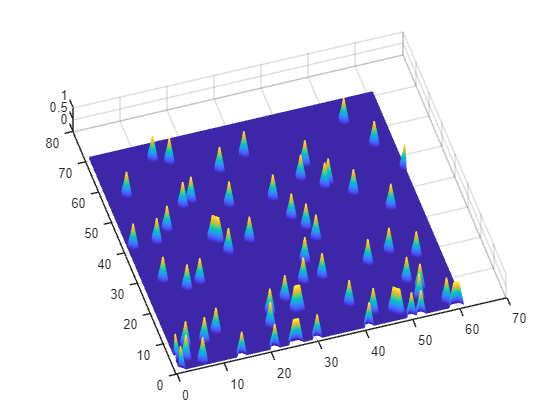

view([-17.489 84.623])